clear
clc
digits(4)

Definizione masse e gravità

% Massa singola ruota
m_r = sym('3');

% Massa asta
m_a = sym('3.5');

% Massa uomo (da far variare poi)
m_c = sym('70');

% Massa carello(base) + batterie
m_b = sym('34.4');

% Massa totale del sistema
M = m_a+m_b+m_c+2*m_r;

% Costante gravitazionale
g = sym('9.81');

Definizione inerzie

% Inerzia asta
J_a = sym('0.1669');

% Inerzia della base
J_b = sym('0.6667');

% Inerzia del corpo (TODO: lungo asse z????)
J_c = 0.5 * m_c * (0.25 ^ 2 + 0.35 ^ 2);

% Inerzia della singola ruota
J_r = sym('0.1452');

Definizione delle altezze [m]

% Altezza asta
h_a = sym('1.4');

% Altezza base
h_b = sym('0.2');

% Profondità base
w_b = sym('0.5');

% Posizione baricentro base (valore assoluto)
z_b = sym('0.1');

% Posizione baricentro corpo umano
h_c = sym('1.70'); % Altezza uomo

% Raggio ruota
r_r = sym('0.22')

$$r\_r = 0.22$$

Definizione delle costanti geometriche a e beta (come in immagine)

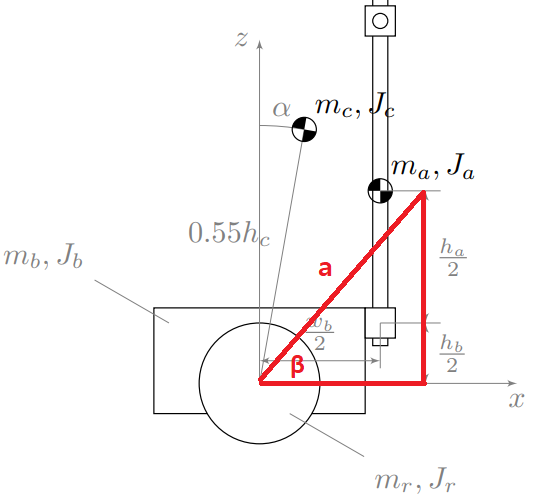

temp_1 = (h_a / 2) + (h_b / 2);
temp_2 = w_b / 2;
l_c = 0.55 * h_c;
l_b = - 0.1;
l_a = vpa(sqrt((temp_1)^2 + (temp_2)^2));

Definizione delle variabili

syms t; % tempo
syms T; % energia cinetica del sistema
syms U; % energia potenziale del sistema
syms alpha; % Angolo di offset statico che sposta in avanti il baricentro
syms beta;%altro angolo statico, vedi disegno
% syms l_c l_a l_b m_a m_c m_r m_b J_r J_b J_a J_c g;
% Coordinate libere
syms x(t); % posizione carrello
vel = diff(x, t); %velocità carello
syms theta(t); % angolo inclinazione
vel_ang = diff(theta, t);%vel angolare
syms b; % Attrito viscoso
syms q_1 q_1_p q_2 q_2_p;
alpha = 0;
beta = vpa(atan(temp_1 / temp_2));


Definisco il problema per il punto Pa

P_a = [x+l_a*sin(theta+beta);l_a*cos(theta+beta);theta];
V_a = diff(P_a,t);
M_a = [m_a,0,0;0,m_a,0;0,0,J_a];
T_a = 1/2 * transpose(V_a) * M_a * V_a;
U_a = m_a * g * l_a*cos(theta+beta);
L_a = T_a - U_a;


Definisco il problema per il punto Pc

P_c = [x+l_c*sin(theta+alpha);l_c*cos(theta+alpha);alpha+theta];
V_c = diff(P_c,t);
M_c = [m_c,0,0;0,m_c,0;0,0,J_c];
T_c = 1/2 * transpose(V_c) * M_c * V_c;
U_c = m_c * g * l_c*cos(alpha+theta);
L_c = T_c - U_c;

Definisco il problema per il punto Pb

P_b = [x+l_b*sin(theta);l_b*cos(theta);theta];
V_b = diff(P_b,t);
M_b = [m_b,0,0;0,m_b,0;0,0,J_b];
T_b = 1/2 * transpose(V_b) * M_b * V_b;
U_b = m_b * g * l_b*cos(theta);
L_b = T_b - U_b;

Definisco il problema per il punto Pr

P_r = [x;0;theta]

$$P\_r(t) = \left(\begin{array}{c} x\left(t\right)\\ 0\\ \theta \left(t\right) \end{array}\right)$$

V_r = diff(P_r,t)

$$V\_r(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)\\ 0\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_r = [m_r,0,0;0,m_r,0;0,0,J_r]

$$M\_r = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 3 & 0\\ 0 & 0 & 0.1452 \end{array}\right)$$

T_r = 1/2 * transpose(V_r) * M_r * V_r

$$T\_r(t) = 0.0726\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\frac{3\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}$$

U_r = 0

U_r = 0

L_r = T_r - U_r

$$L\_r(t) = 0.0726\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\frac{3\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}$$

Eulero Lagrange

L = collect(simplify(2*L_r + L_a + L_b + L_c))

$$L(t) = \begin{array}{l} 27.47\,\sin\left(\theta \left(t\right)\right)-616.9\,\cos\left(\theta \left(t\right)\right)+35.8\,\sigma_{1}+56.95\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}+8.997e-7\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+62.89\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-2.8\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

L_q = subs(L,{x,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p});
dL_dq2p = diff(L_q,q_2_p);
dL_dq2 = diff(L_q,q_2);
dL_dvel_ang = subs(dL_dq2p,{q_1 q_1_p q_2 q_2_p},{x,vel,theta,vel_ang});
dL_dtheta = subs(dL_dq2,{q_1 q_1_p q_2 q_2_p},{x,vel,theta,vel_ang});
dL_dvel_ang_dt = diff(dL_dvel_ang,t);
risultato = collect(simplify(dL_dvel_ang_dt - dL_dtheta))

$$risultato(t) = \begin{array}{l} 62.89\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}-616.9\,\sin\left(\theta \left(t\right)\right)-27.47\,\cos\left(\theta \left(t\right)\right)+8.997e-7\,\left(2\,{\cos\left(\theta \left(t\right)\right)}^{2}-1\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-2.8\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+71.6\,\sigma_{2}+1.799e-6\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

Rrisolviamo per theta2

acc_ang = diff(theta,t,2);
eq2_T = solve(subs(risultato, acc_ang, sym('aux20')), sym('aux20'))

$$eq2\_T = \begin{array}{l} \frac{27.47\,\cos\left(\theta \left(t\right)\right)+616.9\,\sin\left(\theta \left(t\right)\right)-62.89\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}-8.997e-7\,\left(2\,{\cos\left(\theta \left(t\right)\right)}^{2}-1\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+2.8\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}}{1.799e-6\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+71.6}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right) \end{array}$$

Linearizziamo, seguo l'esempio del carroponte; da capire se è giusto o si debba usare anche l'altra equazione

teta2 = eq2_T;
syms u;
teta2_differenziabile = subs(teta2,{x,vel,theta,vel_ang,diff(x,t,2)},{q_1 q_1_p q_2 q_2_p u});
A21 = subs(diff(teta2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},{0,0,0,0,0});
A11 = 0;
A12 = 1;
A22 = subs(diff(teta2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p},{0,0,0,0});
A = [A11 A12;A21 A22]

$$A = \left(\begin{array}{cc} 0 & 1\\ 8.616 & 0 \end{array}\right)$$

B11 = 0;
B21 = subs(diff(teta2_differenziabile,u),{q_1 q_1_p q_2 q_2_p},{0,0,0,0});
B = [B11;B21]

$$B = \left(\begin{array}{c} 0\\ -0.8783 \end{array}\right)$$

C = [1,0]

C =      1     0


D = 0;
syms s G(s);
G = C*(s*eye(2)-A)^-1*B+D

$$G = -\frac{8783.0}{10000.0\,s^{2}-86160.0}$$